### ***THIS FILE CONTAINS THE GREEDY ALGORITHM IMPLEMENTED FOR MODEL REDUCTION***

*Run this file before running the nonlinear optimization.*

***Make sure you correctly download and locate the "****sys_6_bus.mat" ****file before running***

clear all;
warning('off', 'all')
sys_model = load("../../System Model Files/sys_6_bus.mat").sys_6_bus;

%Get the system matrices from the model ss variable
A = sys_model.A;
B = sys_model.B;
C = sys_model.C;
D = sys_model.D;

eig(A)

ans =           -1.16680702891115 +      15.7997238164392i
          -1.16680702891115 -      15.7997238164392i
          -1.16680711683685 +      15.7997238484771i
          -1.16680711683685 -      15.7997238484771i
         -0.582942920755158 +       8.1000826198303i
         -0.582942920755158 -       8.1000826198303i
         -0.582943503194922 +       8.1000793438707i
         -0.582943503194922 -       8.1000793438707i
         -0.419396388152461 +      7.36863540611212i
         -0.419396388152461 -      7.36863540611212i



%Obtain P_fix from C such that
%Image(P_fix) is a superset of Image(C)
function [P_fix,k] = QR(C)             
    [Q,R] = qr(C', 0);            
    s = abs(diag(R));
    k = sum(s > max(size(C))*eps(s(1)));
    Qk = Q(:,1:k);                       
    P_fix = Qk';             
end
%k is the number of fixed states


### ***Function to obtain a matrix R such that Image of (P_f, R) = Image of (P_til)***


%Implemented using SVD
function R = find_orthonormal_proj(P_f, P_til)
    % Find orthonormal matrix R using SVD
    
    % Step 1: Get orthonormal basis for P_til
    [U_til, S_til, ~] = svd(P_til, 'econ');

    tol = 1e-12;   %Define to set values below to zero

    rank_til = sum(diag(S_til) > tol);
    U_til = U_til(:, 1:rank_til);
    
    % Step 2: If P_f is empty, return U_til
    if size(P_f, 2) == 0
        R = U_til;
        return;
    end
    
    % Step 3: Get orthonormal basis for P_f
    [U_f, S_f, ~] = svd(P_f, 'econ');
    rank_f = sum(diag(S_f) > tol);
    U_f = U_f(:, 1:rank_f);
    
    % Step 4: Project U_til onto orthogonal complement of U_f
    projection = U_f * (U_f' * U_til);
    residual = U_til - projection;
    
    % Step 5: Extract orthonormal basis from residual
    [R, S_R, ~] = svd(residual, 'econ');
    rank_R = sum(diag(S_R) > tol);
    R = R(:, 1:rank_R);
end


### ***Function to obtain reduced model using given P,Q matrices***

%Setup the model reduction calculations
function [norm_val, order, sys] = nested_reduced(A,B,C,D,P,Q, norm_type)
    %Setup the pi-matrix required for reduction
    pi_  = Q'*((Q*A*Q')^-1)*Q;  
    
    %Calculate the matrices for reduced model
    A_cap = P*A*P' - P*A*pi_*A*P';
    order = size(A_cap, 1);
    B_cap = (P - P*A*pi_)*B;
    C_cap = C*(P' - pi_*A*P');
    D_cap = D - C*pi_*B;
    
    %Define the original and reduced system
    sys_1 = ss(A,B,C,D);
    sys_2 = ss(A_cap, B_cap,C_cap,D_cap);

    %Calculate norm
    %Trace gives squared H2 norm
    %So squaring here as well
    norm_val = norm(sys_1-sys_2, norm_type)^2;
    sys = sys_2;
end


### ***Greedy Algorithm:***

%Setting up the Greedy Algorithm
%Inputs are Unitary matrix and system matrices
function [optimal_norms, removed_states_optimal, W0] = Optimization(Unitary, A,B,C,D, keep_states,num_rem)

    all_states = 1:size(A, 1); %Size of the model


    keep = keep_states;             %Any states that HAS to be kept
    remaining_states = setdiff(all_states, keep); % all states
    removed_states_optimal = [];   % store the states in the order they are removed.
    optimal_norms = [];            % store the lowest norm found at each step.
    
    num_states_to_remove = num_rem;     %Times to run the iteration
    
    %P_fix remains constant throughout the loop
    %So this part is constant
    %U is obtained as the null-space of P_fix
    %This is to guarantee properties of orthonormality

   
    %Find a matrix transformation such that the transformed system matrix
    %A_tilde is always Negative Definite
    X = lyap(A', eye(size(A,1)));
    L = chol(X);
    
    
    %Find the new P_fix for this transformed C matrix
    [P_fix,~] = QR(C*(L)^-1);
    
    %Define U matrix to be the null space of P_fix
    U = null(P_fix)';

    fprintf('Starting optimal state removal...\n');
   
    %The loop runs as many times as the total states to remove
    for i = 1:num_states_to_remove

        %Placeholder for replacement
        candidate_norms = inf(1, length(remaining_states)); 
       
        %This loop runs as many times as number of states in the model
        for rem = 1:length(remaining_states)
            
            %Remove one state
            candidate_state_to_remove = remaining_states(rem);
            temp_removed = [removed_states_optimal, candidate_state_to_remove];
            temp_remaining = setdiff(all_states, temp_removed);
            
            %Define P,Q matrices based on this and any *past*
            %States removed
            Q = Unitary(temp_removed, :);
            P = Unitary(temp_remaining, :);
            
            %Try reducing the model
            try
               
                [norm_val, ~, ~] = nested_reduced(A, B, C, D, P, Q, 2);
                candidate_norms(rem) = norm_val;
            
            %If the system is unstable
            catch ME
                %fprintf('Warning: Calculation failed for candidate state %d.\n', candidate_state_to_remove);
                %disp(ME);
                %too many warnings. Uncomment if needed! ^^
            end
        end
        %Store all the norms for this reduction step
        

        %Find the min norm for this reduction step
        %Find the index too!
        [min_norm_this_iteration, best_index] = min(candidate_norms);
        
        %Remove the state with the lowest norm
        state_to_permanently_remove = remaining_states(best_index);
        
        %Append this state number to the overall list
        removed_states_optimal = [removed_states_optimal, state_to_permanently_remove];
        remaining_states(best_index) = []; 
        %These are the remaining states

        %Construct P,Q matrix based on removed states
        Q = Unitary(removed_states_optimal, :);
        best_P = Unitary(remaining_states, :);
        %This is the optimal P
        
        %Construct W based on optimal P
        P_til = (best_P*(L)^-1);
       
        
        R = find_orthonormal_proj(P_fix', P_til')';
        
        
        %best_W = best_P * U';
        W0 = R*U';
        P = [P_fix; W0*U];

        %r_now stores the size of the reduced system
        %based on size of P
        r_now = size(P,1);
        
        %Save the W and P matrices
        assignin('base', sprintf('P%d', r_now), P);
        assignin('base', sprintf('W%d', r_now), W0);
        %This W matrix can be used as initialization for
        %more complex nonlinear optimzation
    
        %Store the norm values - just for comparing later
        optimal_norms = [optimal_norms, min_norm_this_iteration];
        
        fprintf('Iteration %2d: Removed State %2d | Reduced Order: %2d | Resulting Norm: %f\n', i, state_to_permanently_remove,r_now,min_norm_this_iteration);
        
    end
    
    fprintf('...Optimization complete.\n\n');
    
    
    disp('Optimal order of removed states:');
    disp(removed_states_optimal);
    
    disp('Norm at each removal step:');
    disp(optimal_norms);
end


%Run greedy optimization 
%Keep the states corresponding to the C matrix
%We have hardcoded this part for this code::
keep_states = [7, 34];   %Keep the frequency at both SM intact

%How many states do you want to remove?
%Depends on the requirement of the reduced order model
num_rem = size(A,1) - size(keep_states,2);
[norms_eye, states_eye, W0] = Optimization(eye(size(A,1)),A,B,C,D, keep_states,num_rem);

Starting optimal state removal...
Iteration  1: Removed State 10 | Reduced Order: 55 | Resulting Norm: 0.000009
Iteration  2: Removed State 37 | Reduced Order: 54 | Resulting Norm: 0.000018
Iteration  3: Removed State 12 | Reduced Order: 53 | Resulting Norm: 0.000030
Iteration  4: Removed State 39 | Reduced Order: 52 | Resulting Norm: 0.000045
Iteration  5: Removed State 15 | Reduced Order: 51 | Resulting Norm: 0.000145
Iteration  6: Removed State 14 | Reduced Order: 50 | Resulting Norm: 0.000145
Iteration  7: Removed State 11 | Reduced Order: 49 | Resulting Norm: 0.000146
Iteration  8: Removed State 13 | Reduced Order: 48 | Resulting Norm: 0.000167
Iteration  9: Removed State 46 | Reduced Order: 47 | Resulting Norm: 0.000339
Iteration 10: Removed State 45 | Reduced Order: 46 | Resulting Norm: 0.000602
Iteration 11: Removed State 19 | Reduced Order: 45 | Resulting Norm: 0.000908
Iteration 12: Removed State 18 | Reduced Order: 44 | Resulting Norm: 0.001365
Iteration 13: Removed State 42

### ***Generate Plots***

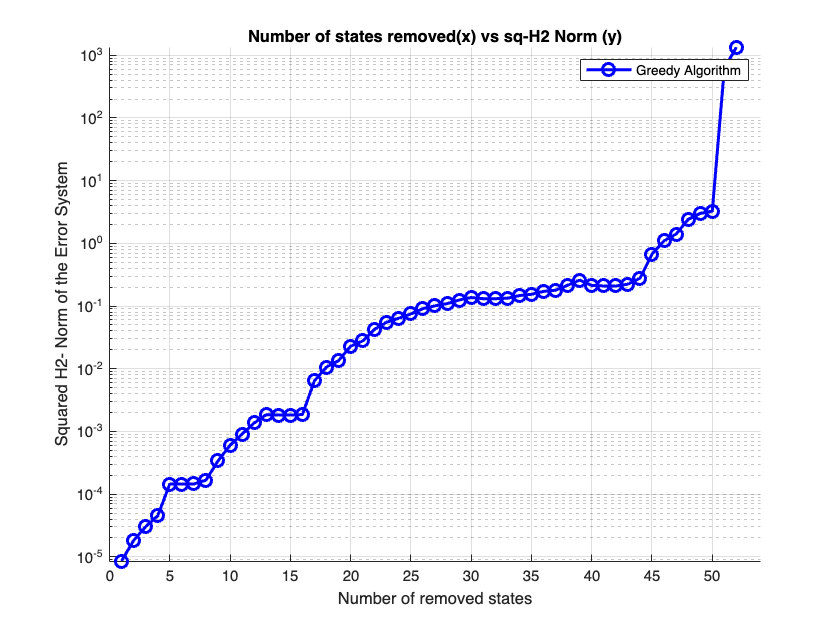

%Plot for norms
function plotWithStyle(optimal_norms, color, displayName)
    y_axis_limit = max(optimal_norms) * 1.1; 
    x_axis_limit = length(optimal_norms);
    
    plot(optimal_norms, '-o', 'LineWidth', 2, 'Color', color, 'MarkerSize', 8, 'DisplayName', displayName); 
    
    xlabel('Number of removed states');
    ylabel('Squared H2- Norm of the Error System');
    legend show;
    axis([0 x_axis_limit 0 y_axis_limit]);

    %Log scale for better analysis when needed
    %Comment this line below out to return to regular y-scale axis
    set(gca, 'YScale', 'log');

    title('Number of states removed(x) vs sq-H2 Norm (y)');
    grid on;
end
%Function to generate a plot

figure;
hold on;
plotWithStyle(norms_eye, "blue", "Greedy Algorithm");
hold off;

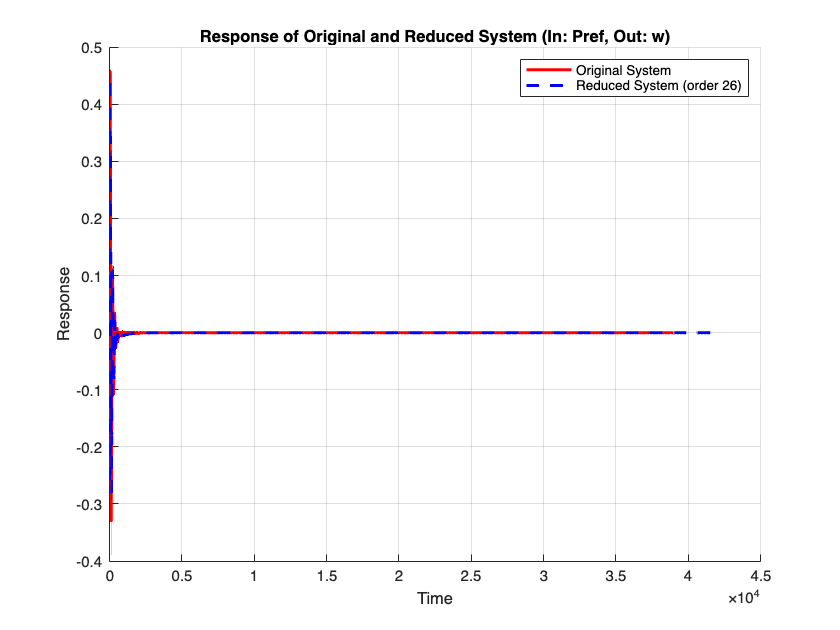

%Generate a Plot for Comparison with Original
function plotWithStyle_impulse(optimal_norms, color, displayName, type)
    
    plot(optimal_norms, type, 'LineWidth', 2, 'Color', color, 'DisplayName', displayName); 
    xlabel('Time');
    ylabel('Response');
    legend show;
    title('Response of Original and Reduced System (In: Pref, Out: w)');
    grid on;
end

%Pick a reduced system order based 
%Example: 1:15 means remove first 15 states
remove_states = states_eye(1:30);  

Unitary = eye(size(A,1));
P_req = Unitary([keep_states, setdiff(setdiff(1:size(A,1), keep_states), remove_states)], :);
Q_req = Unitary(remove_states, :);
%Obtain the reduced order model as sys_red
[norm_val, order, sys_red] = nested_reduced(A,B,C,D,P_req,Q_req, 2);


%Capture the impulse response of the full model - (Input Pref and Output w)
%for this case
[y_full, t_full] = impulse(ss(A,B,C,D), [0 2000]);
y_full_pref_w = y_full(:, 1,4);   %Only store the trajectory of any required input/output combination

%Do similar for reduced system
[y_red, t_red] = impulse(sys_red, [0 2000]);
y_red_pref_w = y_red(:, 1,4);

figure; 
hold on;
plotWithStyle_impulse(y_full_pref_w, "red", "Original System", "-");
plotWithStyle_impulse(y_red_pref_w, "blue", sprintf('Reduced System (order %d)', size(P_req,1)),"--");
hold off;